# **Exercise 3 - Functions**

*This exercise introduces various types of functions: anonymous, in function files, and in (static) class files. *

clear

## Task 1: Anonymous functions with a single input

An *anonymous function* is one that is specified in a single line. When an anonymous function is created, it appears in the workspace as a variable called a *function handle*. An example of an anonymous function is 

myfun = @(x) 3*x;
disp(myfun(2)); % shows 6


$$\mathtt{
myfun = @(x) 3*x; 
}$$


**Task:** Create two fields that are both function handles, the first called `f1`, the second `f2. `

- `f1` should return $f_1(x) = 3 + 2x - 4x^2$.  

- `f2` should return the composite function $f_2(x) = \exp[f_1(x)-1]$.

results.f1 = @(x) FILLIN;
results.f2 = @(x) FILLIN; 

**CHECKING SOLUTION:**

check_answer('exercise_3','task_1', results);

*Note:* if you experience the error `check_answer not found`, try to run `results.f1(0)` in the command window to check if you have a syntax error in your function handle. 

## Task 2: Anonymous functions with multiple inputs

Extending from one to several inputs is simple. For example, 

myfun = @(x,y) x*y+x*2;
disp(myfun(2,2)); % shows 8

**Task:** Create a field called `f` in the struct `results`, defined to be the *Rosenbrock function*: 


$$f(x,y) = (a - x)^2 + b(y-x^2)^2$$


where $a=1$ and $b=1$. 

a = FILLIN; 
b = FILLIN; 
results.f = @(FILLIN) FILLIN; 

**CHECKING SOLUTION:**

check_answer('exercise_3','task_2', results);

## Task 3: Functions

A very important part of becoming a good programmer is to start putting routines into separate functions. It makes code easier to read and pass on and it forces stringency. 

To create a function, you can conveniently right-click in the "current folder" window (by default in the left side) and choose "New file" $\rightarrow$ "Function" (shown below). 

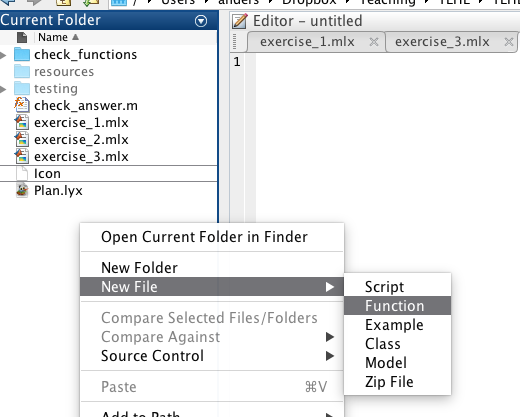

Next, name the file; note that the file **must** have the same name as the function. In the following let's call the function `fun`. Then MATLABfills out some helpful first steps for us: 

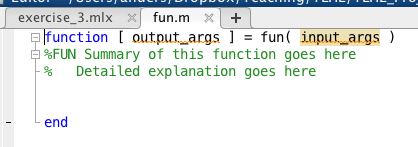

This can be rewritten to

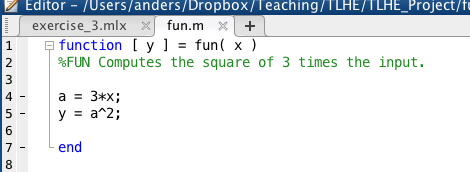

The variable `a` is not returned and will be deleted from memory after the function has finished running. 

**A final note:** functions must be in the same folder as the current working directory of MATLAB (you can display this by entering the command `pwd` in the Command Window. Alternatively, you can ask MATLAB to also include functions located in any folder using the command `addpath('/path/to/folder')`. 

**Task:** Create a function called `fun`, which first computes 


$$a = \exp(x-3)$$


and then finally returns $y$ defined as 


$$y = \sin(\sqrt{a})$$


**CHECKING SOLUTION:**

check_answer('exercise_3','task_3', results);

## Task 4: Mixing functions and anonymous functions

In many applications, it is convenient to use an anonymous function to subsume some of the inputs to another function. For example, if you have a function of two inputs, $f(x,y)$, that you are trying to find the maximum for, you might want to keep $y$ fixed at some number and then maximize $x$. 

**Task:** Create a function file, `rosenbrock.m`, taking two inputs and returning a single output, defined as 


$$f(x,y) = (a - x)^2 + b(y-x^2)^2$$


setting $a=1,b=1$. Next, create a field in `results` called `ros`, which takes a single input and is defined as 


$$\mathtt{ros}(x)=f(x,3)$$


In other words, it is the Rosenbrock function, but with $y=3$ kept fixed. 

*Hint:* If you don't know how to define `results.ros`, re-read the section about accessing other variables from anonymous functions. 

results.ros = @(FILLIN) FILLIN;

**CHECKING SOLUTION:**

check_answer('exercise_3','task_4', results);

## Task 5: Static classes

In some cases, we may have a large number of related functions. This can result in our folder becoming cluttered with function files, so for the sake of being tidy, we can choose to keep all these functions in one file. A MATLAB `class` is one way of doing this.

*Creating a class:* As with a function, right-click in the Current Folder window (in an empty place; don't right-click on another file) and choose "New File" $\rightarrow$ "Class". 

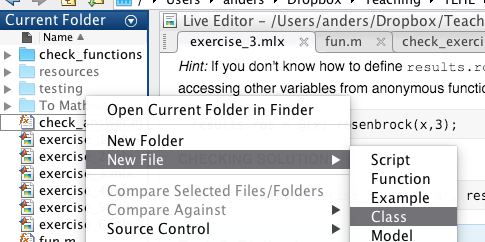

As with a function, the file name must be the same as the name of the class. Let's call it `classy`. Then MATLAB fills out the class in this way: 

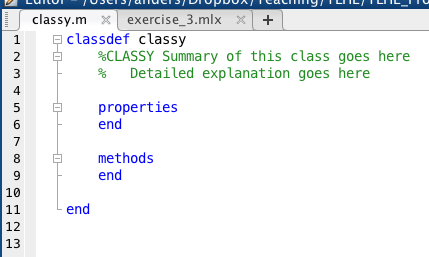

Note that the class doesn't have any inputs or outputs. Also, there are two features of a class; properties and methods, which is "class language" for variables and functions respectively. 

To make the class **static**, we have to make two changes here; 

- Properties must be set to be `Constant`. 

- Methods must be set to be `Static`. 

We need to do this because by default, a class is not static but dynamic. Working with dynamic classes is beyond the scope of this notebook. 

The class might look like this: 

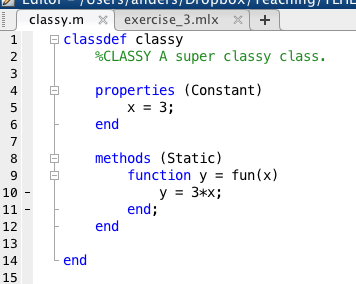

**Property: **The class `classy` has a single property, called `x`. We access this property in the same way that we access fields in a struct; by writing `classy.x`. Note that we cannot change the value of `x` (it is a `Constant` property; only dynamic classes allow for changing properties). 

**Method:** The class `classy` shown above has a single method (function) called `fun`. To use the funciton, we again use dot notation, for example `classy.fun(3)`. If there were additional methods in the class, they could call each other. 

**Task:** Create a class called `classier`. It should have one Constant peroperty called `A` equal to $\pi$. It should have two Static methods: 

- `f1`: should be a function of two variables and return the maximum, i.e. return $f_1(x,y)=\max(\exp(x), Ay)$, where $A$ is equal to `classier.A`.

- `f2:` should be a function of 3 variables and return $f_2(x,y,z)=x+3x f_1(y,z)$. 

Make sure you understand that it is perfectly fine to call variables `y` and `z` in `f2`, even though we denote them `x` and `y` in `f1`. The variable names are "local" to the function and should be thought of as placeholders .

**CHECKING SOLUTION:**

check_answer('exercise_3','task_5', results);